% 
more off;
clear all;
close all;

% Read world data, i.e. landmarks. The true landmark positions are not given to the robot
landmarks = read_world('data/world.dat');
data = read_data('data/sensor_data.dat');

INITIAL_SIGMA = 1000;
N = size(landmarks,2);

% observedLandmarks is a vector that keeps track of which landmarks have been observed so far.
% observedLandmarks(i) will be true if the landmark with id = i has been observed at some point by the robot


## INITIAL BELIEF

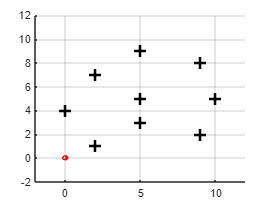

mu = zeros(2*N+3, 1);
robSigma = zeros(3);
robMapSigma = zeros(3,2*N);
mapSigma = INITIAL_SIGMA*eye(2*N);
sigma = [[robSigma robMapSigma];[robMapSigma' mapSigma]];

observedLandmarks = false(1,N);
% signature (mu, sigma, landmarks, timestep, observedLandmarks, z, window)
plot_state(mu, sigma, landmarks, 1, observedLandmarks, data(1).sensor, true);

## EKF LOOP

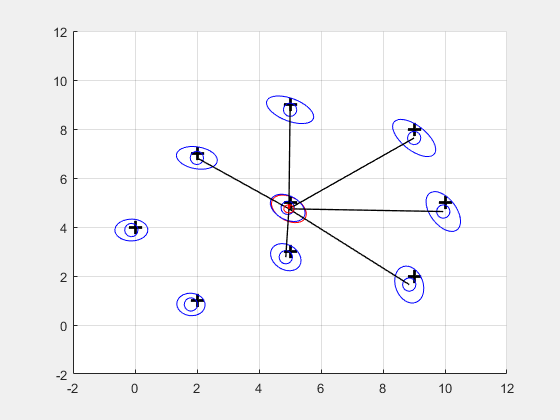

for t = 1:length(data)
    [mu, sigma] = prediction_step(mu, sigma, data(t).odometry);
    [mu, sigma, observedLandmarks] = correction_step(mu, sigma, data(t).sensor, observedLandmarks);

    %Generate visualization plots of the current state of the filter
    skip = 1;
    if mod(t,skip) == 0
        plot_state(mu, sigma, landmarks, t, observedLandmarks, data(t).sensor, false);
    end
    %disp("Current state vector:")
    %disp("mu = "), disp(mu)
end